root_path = "/Users/amithkamath/repo/deep-planner"

root_path = "/Users/amithkamath/repo/deep-planner"

reference_path = fullfile(root_path, "data", "processed-ONL");
predictions_path = fullfile(root_path, "data", "output-ONL", "Prediction");

patient_id = 0:9;

conf_matrix = zeros(10, 10);

for first_idx = patient_id
    for second_idx = patient_id
        first_dose = niftiread(fullfile(reference_path, "DLDP_" + sprintf('%03d', first_idx), "Dose.nii.gz"));
        second_dose = niftiread(fullfile(reference_path, "DLDP_" + sprintf('%03d', second_idx), "Dose.nii.gz"));
        first_mask = niftiread(fullfile(reference_path, "DLDP_" + sprintf('%03d', first_idx), "OpticNerve_L.nii.gz"));
        second_mask = niftiread(fullfile(reference_path, "DLDP_" + sprintf('%03d', second_idx), "OpticNerve_L.nii.gz"));

        masked_first = first_dose(first_mask > 0);
        masked_second = second_dose(second_mask > 0);

        diff = mean(masked_first) - mean(masked_second);
        fprintf("Mean dose score for: " + string(first_idx) + ", " + string(second_idx) + " is: " + string(diff) + "\n")
        conf_matrix(first_idx + 1, second_idx + 1) = diff;
    end
end

Mean dose score for: 0, 0 is: 0
Mean dose score for: 0, 1 is: -0.28361
Mean dose score for: 0, 2 is: 2.0891
Mean dose score for: 0, 3 is: 0.35798
Mean dose score for: 0, 4 is: 3.0279
Mean dose score for: 0, 5 is: 4.8156
Mean dose score for: 0, 6 is: -0.14586
Mean dose score for: 0, 7 is: -7.592
Mean dose score for: 0, 8 is: 2.4028
Mean dose score for: 0, 9 is: -0.43549
Mean dose score for: 1, 0 is: 0.28361
Mean dose score for: 1, 1 is: 0
Mean dose score for: 1, 2 is: 2.3727
Mean dose score for: 1, 3 is: 0.64159
Mean dose score for: 1, 4 is: 3.3115
Mean dose score for: 1, 5 is: 5.0992
Mean dose score for: 1, 6 is: 0.13775
Mean dose score for: 1, 7 is: -7.3084
Mean dose score for: 1, 8 is: 2.6864
Mean dose score for: 1, 9 is: -0.15188
Mean dose score for: 2, 0 is: -2.0891
Mean dose score for: 2, 1 is: -2.3727
Mean dose score for: 2, 2 is: 0
Mean dose score for: 2, 3 is: -1.7312
Mean dose score for: 2, 4 is: 0.93874
Mean dose score for: 2, 5 is: 2.7265
Mean dose score for: 2, 6 is: -2.235

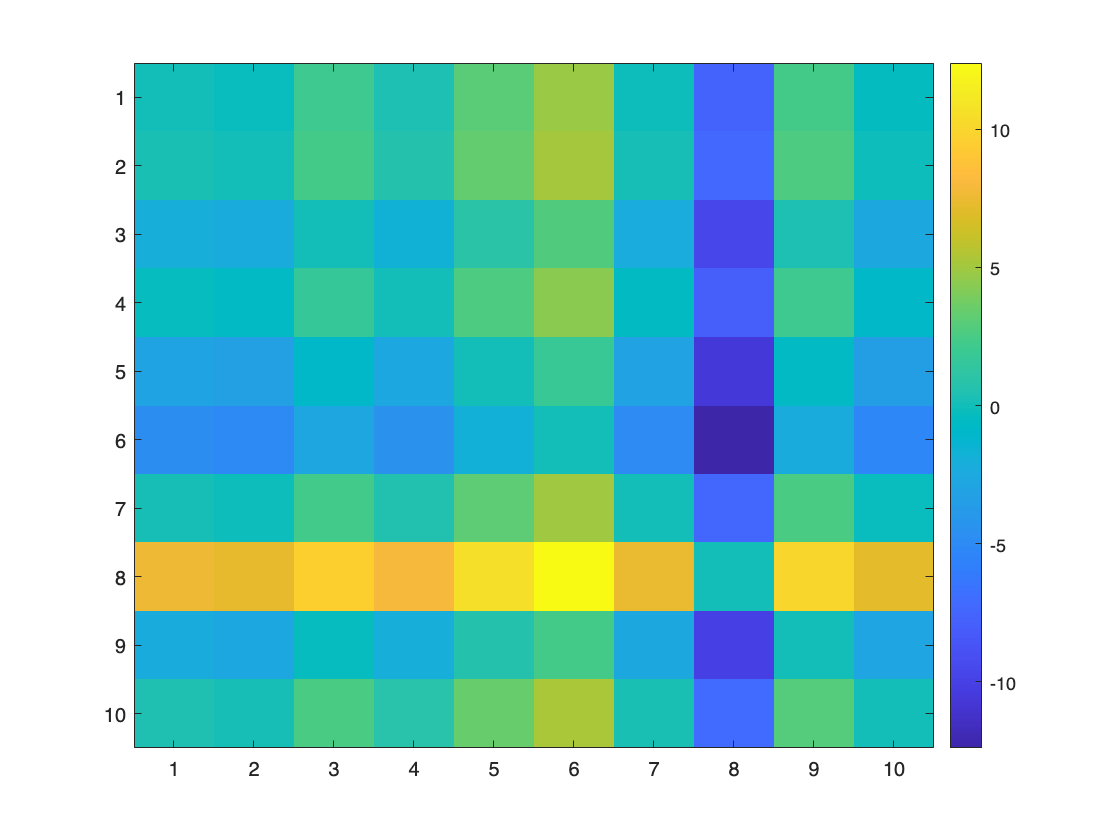

figure, 
imagesc(conf_matrix)
colorbar

patient_id = 0:9;

model_conf_matrix = zeros(10, 10);

for first_idx = patient_id
    for second_idx = patient_id
        first_dose = niftiread(fullfile(predictions_path, "DLDP_" + sprintf('%03d', first_idx), "Dose.nii.gz"));
        second_dose = niftiread(fullfile(predictions_path, "DLDP_" + sprintf('%03d', second_idx), "Dose.nii.gz"));
        first_mask = niftiread(fullfile(reference_path, "DLDP_" + sprintf('%03d', first_idx), "OpticNerve_L.nii.gz"));
        second_mask = niftiread(fullfile(reference_path, "DLDP_" + sprintf('%03d', second_idx), "OpticNerve_L.nii.gz"));

        masked_first = first_dose(first_mask > 0);
        masked_second = second_dose(second_mask > 0);

        diff = mean(masked_first) - mean(masked_second);
        fprintf("Mean dose score for: " + string(first_idx) + ", " + string(second_idx) + " is: " + string(diff) + "\n")
        model_conf_matrix(first_idx + 1, second_idx + 1) = diff;
    end
end

Mean dose score for: 0, 0 is: 0
Mean dose score for: 0, 1 is: -0.22226
Mean dose score for: 0, 2 is: 3.171
Mean dose score for: 0, 3 is: 1.0325
Mean dose score for: 0, 4 is: 1.483
Mean dose score for: 0, 5 is: 5.4367
Mean dose score for: 0, 6 is: -0.41869
Mean dose score for: 0, 7 is: -5.6258
Mean dose score for: 0, 8 is: 2.4875
Mean dose score for: 0, 9 is: -0.51938
Mean dose score for: 1, 0 is: 0.22226
Mean dose score for: 1, 1 is: 0
Mean dose score for: 1, 2 is: 3.3933
Mean dose score for: 1, 3 is: 1.2548
Mean dose score for: 1, 4 is: 1.7053
Mean dose score for: 1, 5 is: 5.6589
Mean dose score for: 1, 6 is: -0.19643
Mean dose score for: 1, 7 is: -5.4035
Mean dose score for: 1, 8 is: 2.7098
Mean dose score for: 1, 9 is: -0.29712
Mean dose score for: 2, 0 is: -3.171
Mean dose score for: 2, 1 is: -3.3933
Mean dose score for: 2, 2 is: 0
Mean dose score for: 2, 3 is: -2.1385
Mean dose score for: 2, 4 is: -1.688
Mean dose score for: 2, 5 is: 2.2657
Mean dose score for: 2, 6 is: -3.5897
Me

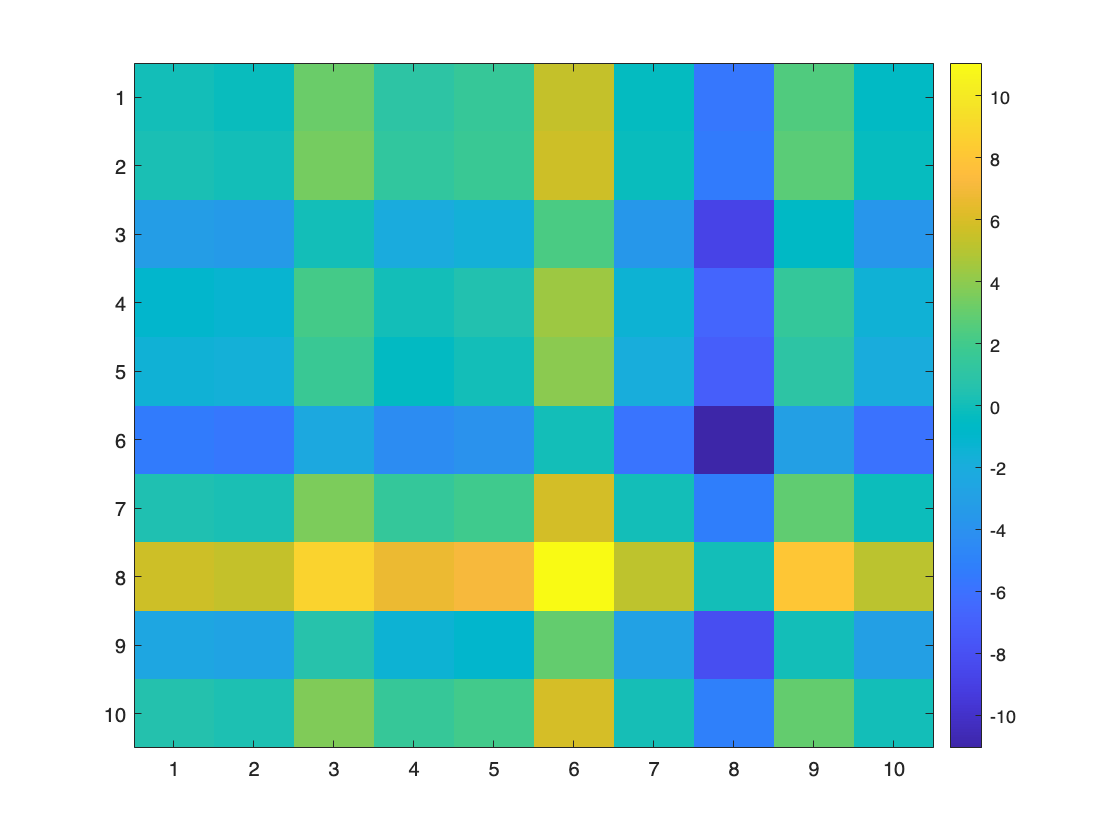

figure, 
imagesc(model_conf_matrix)
colorbar